% === Configuração do ROS ===
clc; clear all; close all;
setenv('ROS_MASTER_URI','http://192.168.245.132:11311');
setenv('ROS_IP','192.168.245.1');
rosshutdown;

Shutting down global node /matlab_global_node_24531 with NodeURI http://192.168.245.1:54489/ and MasterURI http://192.168.245.132:11311.


rosinit('192.168.245.132', 11311);

The value of the ROS_IP environment variable, 192.168.245.1, will be used to set the advertised address for the ROS node.
Initializing global node /matlab_global_node_05558 with NodeURI http://192.168.245.1:54530/ and MasterURI http://192.168.245.132:11311.


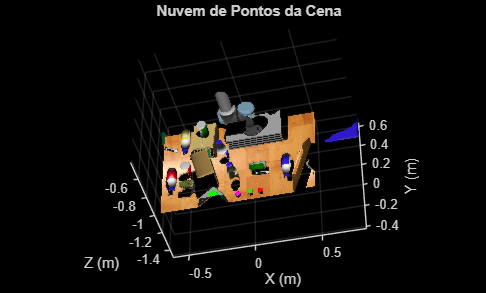

% === Captura da nuvem de pontos do sensor ===
pcSub = rossubscriber('/camera/depth/points', 'sensor_msgs/PointCloud2', 'DataFormat', 'struct');
pause(1);
pcMsg = receive(pcSub, 3);

% Extrai XYZ
xyz = rosReadXYZ(pcMsg, "PreserveStructureOnRead", true);
xyzVec = reshape(xyz, [], 3);

% Extrai RGB (opcional)
try
    rgb = rosReadRGB(pcMsg, "PreserveStructureOnRead", true);
    rgbVec = reshape(rgb, [], 3);
    hasColor = true;
catch
    hasColor = false;
end

% Remove NaNs
valid = ~any(isnan(xyzVec), 2);
xyzClean = xyzVec(valid, :);
xyzClean(:,3) = -xyzClean(:,3);  % Inverte o eixo Z para alinhar com câmera

% Cria ptCloud da cena
if hasColor
    rgbClean = uint8(255 * rgbVec(valid, :));
    ptCena = pointCloud(xyzClean, "Color", rgbClean);
else
    ptCena = pointCloud(xyzClean);
end

% Mostrar cena
figure;
pcshow(ptCena, VerticalAxis="Y", VerticalAxisDir="Up");
title("Nuvem de Pontos da Cena");
xlabel("X (m)"); ylabel("Y (m)"); zlabel("Z (m)");

% % === Importar modelo ===
% gm = importGeometry("C:\Users\pecci\OneDrive\Desktop\Modelos_garra\canYellow.stl");
% pdemModel = createpde();
% pdemModel.Geometry = gm;
% generateMesh(pdemModel, 'Hmax', 1.0);  %Geração da malha refinada
% 
% % === Extrair nós da malha e converter para metros (modelo vem em mm)
% nodes = pdemModel.Mesh.Nodes';     % Transpor de 3xN para N×3
% nodes = nodes * 0.03;              % Corrigir escala (mm → m → fator de 10x menor)
% 
% % Criar nuvem de pontos do modelo
% ptCloudModel = pointCloud(nodes);
% 
% % % Mostrar modelo corretamente
% % figure;
% % pcshow(ptCloudModel, VerticalAxis="Y", VerticalAxisDir="Up");
% % title("Nuvem de Pontos do Modelo");
% % xlabel("X (m)"); ylabel("Y (m)"); zlabel("Z (m)");

% ==Importar modelo superfície==
% Leitura do STL
%meshData = stlread("C:\Users\pecci\OneDrive\Desktop\Modelos_garra\canYellow.stl");
meshData = stlread("C:\Users\pecci\OneDrive\Desktop\Modelos_garra\bottle.stl");
% Detectar o tipo de retorno
if isa(meshData, "triangulation")
    % Já está no formato correto
    tri = meshData;
    
elseif isstruct(meshData) && all(isfield(meshData, ["Points", "ConnectivityList"]))
    % Estrutura retornada por stlread moderno
    tri = triangulation(meshData.ConnectivityList, meshData.Points);
    
elseif iscell(meshData)
    % Se for uma célula: [faces, vertices] = stlread(...)
    [faces, vertices] = meshData{:};
    tri = triangulation(faces, vertices);
    
else
    error("Formato de saída de stlread não reconhecido.");
end

% Gerar nuvem de pontos com mesh2pc
ptModelo = mesh2pc(tri, ...
    NumPoints=5000, ...
    SamplingMethod="PoissonDiskSampling");

%correção de escala
scaleFactor = 0.034;% Fator de escala
ptCloudScaled = pointCloud(ptModelo.Location * scaleFactor);
if ~isempty(ptModelo.Normal)% Preservar as normais, se existirem
    ptCloudScaled.Normal = ptModelo.Normal;
end

% Visualização
figure('Name','Nuvem de Pontos da Malha STL','Color','w');
pcshow(ptCloud, 'MarkerSize', 30);
title('Nuvem de Pontos do Modelo STL');
xlabel('X'); ylabel('Y'); zlabel('Z');
axis equal; grid on;
view(3);

% ==Importar modelo superfície sem a parte de baixo==
meshData = stlread("C:\Users\pecci\OneDrive\Desktop\Modelos_garra\bottle.stl");

% Detectar o tipo de retorno
if isa(meshData, "triangulation")
    tri = meshData;

elseif isstruct(meshData) && all(isfield(meshData, ["Points", "ConnectivityList"]))
    tri = triangulation(meshData.ConnectivityList, meshData.Points);

elseif iscell(meshData)
    [faces, vertices] = meshData{:};
    tri = triangulation(faces, vertices);

else
    error("Formato de saída de stlread não reconhecido.");
end

% ==Gerar nuvem de pontos==
ptModelo = mesh2pc(tri, ...
    NumPoints=5000, ...
    SamplingMethod="PoissonDiskSampling");

% ==Aplicar correção de escala==
scaleFactor = 0.034; % Fator de escala
locationsScaled = ptModelo.Location * scaleFactor;

% ==Remover pontos com z < 0==
idx_valid = locationsScaled(:,3) >= 0;
locationsFiltered = locationsScaled(idx_valid, :);

% Criar nova nuvem com pontos válidos
ptCloudScaled = pointCloud(locationsFiltered);

% Se existirem normais, manter apenas as correspondentes
if ~isempty(ptModelo.Normal)
    ptCloudScaled.Normal = ptModelo.Normal(idx_valid, :);
end

% % ==Visualização==
% figure('Name','Nuvem de Pontos da Malha STL','Color','w');
% pcshow(ptCloudScaled, 'MarkerSize', 30);
% title('Nuvem de Pontos do Modelo STL (Z >= 0)');
% xlabel('X'); ylabel('Y'); zlabel('Z');
% axis equal; grid on;
% view(3);

% % === Importar modelo superfície superior ===
% % Leitura do STL
% meshData = stlread("C:\Users\pecci\OneDrive\Desktop\Modelos_garra\bottle.stl");
% 
% % Detectar o tipo de retorno
% if isa(meshData, "triangulation")
%     tri = meshData;
% 
% elseif isstruct(meshData) && all(isfield(meshData, ["Points", "ConnectivityList"]))
%     tri = triangulation(meshData.ConnectivityList, meshData.Points);
% 
% elseif iscell(meshData)
%     [faces, vertices] = meshData{:};
%     tri = triangulation(faces, vertices);
% 
% else
%     error("Formato de saída de stlread não reconhecido.");
% end
% 
% % ==Gerar nuvem de pontos com mesh2pc==
% ptModelo = mesh2pc(tri, ...
%     NumPoints=5000, ...
%     SamplingMethod="PoissonDiskSampling");
% 
% % ==Filtrar somente a vista superior==
% if ~isempty(ptModelo.Normal)
%     % Usar normais: manter pontos com normais apontando majoritariamente para cima (Z+)
%     idx_up = ptModelo.Normal(:,3) > cosd(60);  % ângulo de corte de 60°
% else
%     % Se não houver normais: usar altura Z para manter os 25% mais altos
%     zcoords = ptModelo.Location(:,3);
%     z_min = prctile(zcoords, 75);  % top 25%
%     idx_up = zcoords >= z_min;
% end
% 
% % Criar nuvem filtrada
% ptUp = select(ptModelo, idx_up);
% 
% % ==Correção de escala==
% scaleFactor = 0.034; % Fator de escala
% ptCloudScaled = pointCloud(ptUp.Location * scaleFactor);
% if ~isempty(ptUp.Normal)
%     ptCloudScaled.Normal = ptUp.Normal;
% end
% 
% % ==Visualização==
% figure
% pcshow(ptCloudScaled, ...
%     ViewPlane="XY", ...
%     VerticalAxis="Z", ...
%     VerticalAxisDir="Up");
% title("Nuvem de Pontos - Vista Superior");


% % 1. Importe o modelo (STL)
% gm = importGeometry("C:\Users\pecci\OneDrive\Desktop\Modelos_garra\canYellow.stl");
% pdemModel = createpde();
% pdemModel.Geometry = gm;
% 
% % 2. Gere a malha volumétrica (tetraedros) ou de superfície
% generateMesh(pdemModel, 'Hmax', 1.0);
% 
% % 3. Obtenha vértices e faces da malha
% nodes = pdemModel.Mesh.Nodes';        % N×3
% elements = pdemModel.Mesh.Elements';  % M×4 (tetrahedros)
% 
% % 4. Extraia a malha de superfície (triângulos)
% facets = [elements(:,[1 2 3]);
%           elements(:,[1 2 4]);
%           elements(:,[1 3 4]);
%           elements(:,[2 3 4])];
% facets = unique(sort(facets,2), 'rows');
% faces = facets(:,:);  % Nf×3
% 
% % 5. Converta para point cloud apenas da superfície
% ptCloudSurface = mesh2pc(nodes, faces, ...
%     NumPoints = 5000, ...             % controle de densidade
%     SamplingMethod = "PoissonDiskSampling");
% 
% % 6. Ajuste de escala para metros
% ptCloudSurface.Location = ptCloudSurface.Location * 0.001;  % mm → m
% 
% % 7. Visualize
% figure;
% pcshow(ptCloudSurface, VerticalAxis="Y", VerticalAxisDir="Up");
% title("Nuvem de Pontos da Superfície");
% xlabel("X (m)"); ylabel("Y (m)"); zlabel("Z (m)");

% % === Comparação: cena vs modelo (mesmo sistema de coordenadas)
% figure;
% pcshowpair(ptCloudScaled, ptCena, 'VerticalAxis','Y','VerticalAxisDir','Up');
% title("Comparação de Tamanho: Modelo vs Cena");
% legend("Modelo", "Cena");
% xlabel("X (m)"); ylabel("Y (m)"); zlabel("Z (m)");

% === Filtro de planos ===
ptFiltrada = ptCena;
planes = 0;
while true
    [planeModel, inlierIdx, ~] = pcfitplane(ptFiltrada, 0.01);
    if numel(inlierIdx) < 20000  % Ignorar planos pequenos
        break
    end
    ptFiltrada = select(ptFiltrada, setdiff(1:ptFiltrada.Count, inlierIdx));
    planes = planes + 1;
end

ptCenaSemPlano = ptFiltrada;
fprintf("Removidos %d planos principais.\n", planes);

Removidos 2 planos principais.



% Mostrar cena sem planos
figure;
pcshow(ptCenaSemPlano, VerticalAxis="Y", VerticalAxisDir="Up");
title("Nuvem de Pontos da Cena");
xlabel("X (m)"); ylabel("Y (m)"); zlabel("Z (m)");

% % 1. Carregar e preprocessar
% template = ptCloudScaled;
% scene    = ptCenaSemPlano;
% sceneDS  = pcdownsample(scene, 'gridAverage', 0.02);
% 
% % 2. Extrair características
% [featT, indT] = extractFPFHFeatures(template);
% [featS, indS] = extractFPFHFeatures(sceneDS);
% 
% % 3. Corresponder características (com conversão para evitar erro)
% fixedCloud  = pointCloud(single(select(template, indT).Location));
% movingCloud = pointCloud(single(select(sceneDS, indS).Location));
% 
% [pairs, scores] = pcmatchfeatures(featT, featS, ...
%   fixedCloud, movingCloud);
% 
% % 4. Obter correspondências e alinhar
% fixed  = select(template, pairs(:,1));
% moving = select(sceneDS, pairs(:,2));
% 
% fprintf('Total de pares: %d\n', size(pairs,1));
% fprintf('Pontos únicos no modelo: %d\n', numel(unique(pairs(:,1))));
% fprintf('Pontos únicos na cena:   %d\n', numel(unique(pairs(:,2))));
% 
% tform0 = pcregistericp(fixed, moving, 'MaxIterations', 30);
% 
% alignedTemplate = pctransform(template, tform0);
% 
% % 5. Avaliar qualidade do alinhamento
% [~, dists] = findNearestNeighbors(sceneDS, ...
%   alignedTemplate.Location, 1);
% ratio = sum(dists < 0.03) / numel(dists);
% fprintf('Ajuste: %.1f%% dos pontos a <3 cm\n', ratio * 100);
% 

% % 1. Registro via ICP (point-to-plane para maior precisão)
% [tform, movingReg, rmse] = pcregistericp(template, scene, ...
%     'Metric', 'pointToPlane');
% 
% % 2. Extrair translação (em metros, por exemplo)
% translation = tform.Translation;  % [tx, ty, tz]
% 
% % 3. Extrair rotação (matriz 3×3)
% R = tform.Rotation;  
% 
% % 4. (Opcional) Converter rotação para ângulos Euler
% angles = rotm2eul(R, 'ZYX'); % [yaw, pitch, roll]

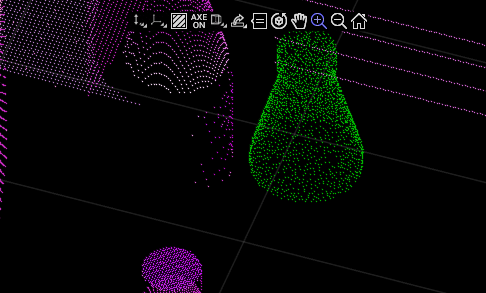

%== FGR ==

%simplifica a nuvem e tira ruido
grid = 0.001;
mdl_ds = pcdownsample(ptCloudScaled, 'gridAverage', grid);
scn_ds = pcdownsample(ptCenaSemPlano, 'gridAverage', grid);

% Execute o FGR
tformGlobal = pcregisterfgr(mdl_ds, scn_ds, grid, MaxIterations=100);

% Visualize o alinhamento global
ptModelGlobal = pctransform(ptCloudScaled, tformGlobal); % Cria modelo alinhado com o detectado
figure;
pcshowpair(ptCenaSemPlano, ptModelGlobal);
title('Alinhamento Global (FGR)');

% === Extrai translação e rotação da transformação global ===

% Translação (posição XYZ)
posicao_xyz = tformGlobal.Translation;  % [X, Y, Z] em metros

% Rotação: converte matriz de rotação para ângulos de Euler (rad)
rot_rad = rotm2eul(tformGlobal.Rotation, 'ZYX');  % Ordem: Z (yaw), Y (pitch), X (roll)

% Converte para graus
rot_deg = rad2deg(rot_rad);  % [yaw, pitch, roll] em graus

% === Exibe os resultados ===
fprintf('Posição do objeto na cena:\n');

Posição do objeto na cena:


fprintf('  X: %.3f m\n', posicao_xyz(1));

  X: -0.015 m


fprintf('  Y: %.3f m\n', posicao_xyz(2));

  Y: -0.017 m


fprintf('  Z: %.3f m\n', posicao_xyz(3));

  Z: -0.929 m



fprintf('\nOrientação (ângulos de Euler em graus - ZYX):\n');


Orientação (ângulos de Euler em graus - ZYX):


fprintf('  Yaw  (Z): %.2f°\n', rot_deg(1));

  Yaw  (Z): -0.00°


fprintf('  Pitch(Y): %.2f°\n', rot_deg(2));

  Pitch(Y): -0.00°


fprintf('  Roll (X): %.2f°\n', rot_deg(3));

  Roll (X): -0.00°


% o Método ICP tem uma ideia parecida porém é usado para alinhamento muito
% mais precisos por isso não funiona bem para buscar correspondentes em
% cenários ele poderia ser usado para refinar o alinhamento ao coletar a
% posição do objeto e usando o ICP ára analisar só aquela pequena área